# Racing Line Optimizer

### Import track data

track = readmatrix("Austin.csv")

track = 	1.0e+03 *

    0.0010    0.0040    0.0076    0.0074
    0.0049    0.0010    0.0076    0.0074
    0.0089   -0.0021    0.0076    0.0074
    0.0129   -0.0051    0.0076    0.0074
    0.0169   -0.0081    0.0076    0.0074
    0.0208   -0.0112    0.0077    0.0075
    0.0248   -0.0142    0.0077    0.0075
    0.0288   -0.0172    0.0077    0.0075
    0.0328   -0.0203    0.0077    0.0075
    0.0367   -0.0233    0.0077    0.0075


### Define variables

trackName = 'Austin';
m = 750; % Mass of vehicle
ftmax = 16; % Max acceleration (m/s^2)
fbmax = 18; % Min acceleration (m/s^2)
fnmax = 30; % Max cornering acceleration (m/s^2)

### Generate optimized path

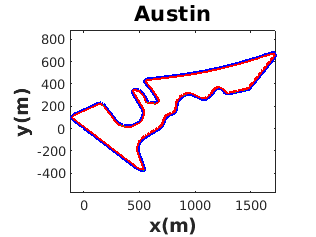

 Iter            Fval  Primal Infeas    Dual Infeas  Complementarity  
    0   -6.119811e+01   0.000000e+00   2.988115e+01     1.000000e+00  
    1   -7.929944e+01   0.000000e+00   1.494058e-02     2.502501e-01  
    2   -8.213824e+01   0.000000e+00   2.121122e-04     2.766499e-02  
    3   -8.415030e+01   5.551115e-17   6.957591e-07     2.962250e-03  
    4   -8.457917e+01   2.720046e-15   5.649711e-08     3.824004e-04  
    5   -8.460758e+01   1.054712e-15   1.616616e-08     1.151911e-04  
    6   -8.461576e+01   1.769418e-15   3.439353e-09     3.466656e-05  
    7   -8.461720e+01   2.081668e-17   1.118088e-09     1.253760e-05  
    8   -8.461756e+01   8.899131e-16   2.820719e-10     3.386589e-06  
    9   -8.461765e+01   1.275022e-16   4.650619e-11     2.499003e-07  
   10   -8.461767e+01   3.174544e-16   8.848984e-12     6.907631e-08  
   11   -8.461767e+01   3.061787e-16   7.471074e-12     6.003952e-08  
   12   -8.461767e+01   1.977585e-16   6.252592e-13     5.785551e-08  
   13 

xresMCP = 	1.0e+03 *

   -0.0036
   -0.0007
    0.0022
    0.0052
    0.0081
    0.0110
    0.0139
    0.0168
    0.0198
    0.0227


yresMCP =    -1.9279
   -4.1559
   -6.3838
   -8.6118
  -10.8398
  -13.0679
  -15.2960
  -17.5241
  -19.7522
  -21.9803


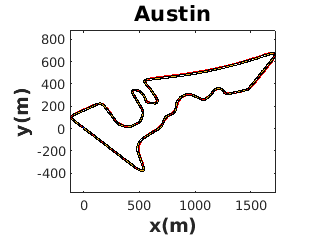

[trajMCP, trackData] = minCurvaturePathGenFunction(track,trackName);

% Click on the drop down menu to select the method for generating the optimized path

### Generate velocity profile

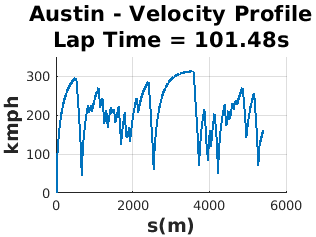

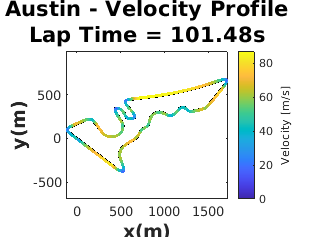

[velProf,len] = velProfCalcFunction(trajMCP,trackName,m,ftmax,fbmax,fnmax,trackData);

### References:

- The Silverstone racetrack data has been ta    ken from the following GitHub repository: [https://github.com/TUMFTM/racetrack-database](https://github.com/TUMFTM/racetrack-database) 

- The function, "velProfCalcFunction" uses the function, "curvature" that has been taken from the following File Exchange: [https://www.mathworks.com/matlabcentral/fileexchange/69452-curvature-of-a-1d-curve-in-a-2d-or-3d-space](https://www.mathworks.com/matlabcentral/fileexchange/69452-curvature-of-a-1d-curve-in-a-2d-or-3d-space) 